clear all
% Create MainTank object from gmt_Tank class
MainTank = gmt_Tank("MainTank")

MainTank =   gmt_Tank with properties:

                   Name: "MainTank"
             EdgeMatrix: [4×2 double]
                  Edges: [1×4 gmt_Edge]
               Vertices: [1×6 gmt_Vertex]
             Properties: [1×1 gmt_GraphProperties]
                DiGraph: [1×1 digraph]
                 Inputs: ["u1"    "u2"]
              InputData: [1×2 gmt_Input]
                 States: ["x1"    "x2"]
                Outputs: [0×1 string]
        ModelParameters: [1×3 gmt_Parameter]
        SystemEquations: [1×1 struct]
    SystemEquationsSubs: [1×1 struct]
      InitialConditions: []
          ModelMetadata: [1×1 struct]
                  Ports: [1×2 gmt_Port]


% Run Initial Condition Report
MainTank.gmt_ReportInitCon


          Vertex Name          Vertex State Variable    Initial Condition    State Variable Units
    _______________________    _____________________    _________________    ____________________

    "MainTank: Temperature"            "x1"               "Unassigned"               "K"         
    "MainTank: Mass"                   "x2"               "Unassigned"               "kg"        



% Add Initial Conditions After Object Created
MainTank.gmt_InitCon([300,6000])

ans =   gmt_Tank with properties:

                   Name: "MainTank"
             EdgeMatrix: [4×2 double]
                  Edges: [1×4 gmt_Edge]
               Vertices: [1×6 gmt_Vertex]
             Properties: [1×1 gmt_GraphProperties]
                DiGraph: [1×1 digraph]
                 Inputs: ["u1"    "u2"]
              InputData: [1×2 gmt_Input]
                 States: ["x1"    "x2"]
                Outputs: [0×1 string]
        ModelParameters: [1×3 gmt_Parameter]
        SystemEquations: [1×1 struct]
    SystemEquationsSubs: [1×1 struct]
      InitialConditions: [300 6000]
          ModelMetadata: [1×1 struct]
                  Ports: [1×2 gmt_Port]


% Add Initial Conditions During Object Creation  
clear MainTank 
MainTank = gmt_Tank("MainTank","InitCon",[300,6000])

MainTank =   gmt_Tank with properties:

                   Name: "MainTank"
             EdgeMatrix: [4×2 double]
                  Edges: [1×4 gmt_Edge]
               Vertices: [1×6 gmt_Vertex]
             Properties: [1×1 gmt_GraphProperties]
                DiGraph: [1×1 digraph]
                 Inputs: ["u1"    "u2"]
              InputData: [1×2 gmt_Input]
                 States: ["x1"    "x2"]
                Outputs: [0×1 string]
        ModelParameters: [1×3 gmt_Parameter]
        SystemEquations: [1×1 struct]
    SystemEquationsSubs: [1×1 struct]
      InitialConditions: [300 6000]
          ModelMetadata: [1×1 struct]
                  Ports: [1×2 gmt_Port]




% Generate Model Report
MainTank.gmt_ReportFull


Graph Report

                 Vertex Name                 Vertex Type    Vertex State Variable    State Variable Units    Capacitance Inputs    Capacitance    Capacitance Equation                   Power Equation                
    _____________________________________    ___________    _____________________    ____________________    __________________    ___________    ____________________    _____________________________________________

    "MainTank: Temperature"                  "Internal"             "x1"                     "K"                     ""             "cp_f*x2"       "cp_f*x2*x1_dot"      "cp_f*u1*x4 - cp_f*u2*x1 - cp_f*x1*(u1 - u2)"
    "MainTank: Mass"                         "I

% Plot Graph Model 
%MainTank.gmt_PlotGraph
% Build Simulation Model 
pathname = "C:\Users\jmp8430\Documents\Research\GraphModel_ToolboxV2\doc";
MainTank = gmt_Tank("MainTank","BuildSim",pathname,"InitCon",[300,6000])

MainTank =   gmt_Tank with properties:

                   Name: "MainTank"
             EdgeMatrix: [4×2 double]
                  Edges: [1×4 gmt_Edge]
               Vertices: [1×6 gmt_Vertex]
             Properties: [1×1 gmt_GraphProperties]
                DiGraph: [1×1 digraph]
                 Inputs: ["u1"    "u2"]
              InputData: [1×2 gmt_Input]
                 States: ["x1"    "x2"]
                Outputs: [0×1 string]
        ModelParameters: [1×3 gmt_Parameter]
        SystemEquations: [1×1 struct]
    SystemEquationsSubs: [1×1 struct]
      InitialConditions: [300 6000]
          ModelMetadata: [1×1 struct]
                  Ports: [1×2 gmt_Port]


% Model Linearization
% Add Third Outputfor linearization around trajectories
[A, B] = MainTank.gmt_ControlModel

$$A(x1, x2, u1, u2) = \left(\begin{array}{cc} -\frac{{\mathrm{cp}}_{f}\,u_{2}+{\mathrm{cp}}_{f}\,\left(u_{1}-u_{2}\right)}{{\mathrm{cp}}_{f}\,x_{2}} & \frac{{\mathrm{cp}}_{f}\,u_{2}\,x_{1}-{\mathrm{cp}}_{f}\,u_{1}\,x_{4}+{\mathrm{cp}}_{f}\,x_{1}\,\left(u_{1}-u_{2}\right)}{{\mathrm{cp}}_{f}\,{x_{2}}^{2}}\\ 0 & 0 \end{array}\right)$$

$$B(x1, x2, u1, u2) = \left(\begin{array}{cc} -\frac{{\mathrm{cp}}_{f}\,x_{1}-{\mathrm{cp}}_{f}\,x_{4}}{{\mathrm{cp}}_{f}\,x_{2}} & 0\\ 1 & -1 \end{array}\right)$$

% Model Linearizaiton with Simplfication 
[A, B] = MainTank.gmt_ControlModel("Simplify",true)

$$A(x1, x2, u1, u2) = \left(\begin{array}{cc} -\frac{u_{1}}{x_{2}} & \frac{u_{1}\,\left(x_{1}-x_{4}\right)}{{x_{2}}^{2}}\\ 0 & 0 \end{array}\right)$$

$$B(x1, x2, u1, u2) = \left(\begin{array}{cc} -\frac{x_{1}-x_{4}}{x_{2}} & 0\\ 1 & -1 \end{array}\right)$$

% Model Linearization with Parameter Value Substitution 
[A, B] = MainTank.gmt_ControlModel("NumSub",true)

$$A(x1, x2, u1, u2) = \left(\begin{array}{cc} -\frac{u_{1}}{x_{2}} & \frac{3300\,u_{2}\,x_{1}-3300\,u_{1}\,x_{4}+3300\,x_{1}\,\left(u_{1}-u_{2}\right)}{3300\,{x_{2}}^{2}}\\ 0 & 0 \end{array}\right)$$

$$B(x1, x2, u1, u2) = \left(\begin{array}{cc} -\frac{3300\,x_{1}-3300\,x_{4}}{3300\,x_{2}} & 0\\ 1 & -1 \end{array}\right)$$

% Model Linearizaiton and Discretization 
[Ad, Bd] = MainTank.gmt_ControlModel("Discrete",0.100)

$$Ad(x1, x2, u1, u2) = \left(\begin{array}{cc} {\mathrm{e}}^{-\frac{{\mathrm{cp}}_{f}\,u_{2}+{\mathrm{cp}}_{f}\,\left(u_{1}-u_{2}\right)}{10\,{\mathrm{cp}}_{f}\,x_{2}}} & {\mathrm{e}}^{\frac{{\mathrm{cp}}_{f}\,u_{2}\,x_{1}-{\mathrm{cp}}_{f}\,u_{1}\,x_{4}+{\mathrm{cp}}_{f}\,x_{1}\,\left(u_{1}-u_{2}\right)}{10\,{\mathrm{cp}}_{f}\,{x_{2}}^{2}}}\\ 1 & 1 \end{array}\right)$$

$$Bd(x1, x2, u1, u2) = \begin{array}{l} \left(\begin{array}{cc} \sigma_{1}-\frac{x_{1}\,{\mathrm{e}}^{\frac{u_{1}}{10\,x_{2}}}\,\left({\mathrm{e}}^{\frac{{\mathrm{e}}^{-\frac{u_{1}}{10\,x_{2}}}}{10}}-1\right)}{x_{2}}+\frac{x_{4}\,{\mathrm{e}}^{\frac{u_{1}}{10\,x_{2}}}\,\left({\mathrm{e}}^{\frac{{\mathrm{e}}^{-\frac{u_{1}}{10\,x_{2}}}}{10}}-1\right)}{x_{2}} & -\sigma_{1}\\ \frac{\left({\mathrm{e}}^{1/10}-1\right)\,\left(x_{2}-x_{1}+x_{4}\right)}{x_{2}} & 1-{\mathrm{e}}^{1/10} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\frac{u_{1}\,x_{1}}{10\,{x_{2}}^{2}}}\,{\mathrm{e}}^{\frac{u_{1}\,x_{4}}{10\,{x_{2}}^{2}}}\,\left({\mathrm{e}}^{\frac{{\mathrm{e}}^{\frac{u_{1}\,x_{1}}{10\,{x_{2}}^{2}}}\,{\mathrm{e}}^{-\frac{u_{1}\,x_{4}}{10\,{x_{2}}^{2}}}}{10}}-1\right) \end{array}$$

% Python Exporting Without Parameter Value Substition 
 MainTank.SystemEquations.Expression

$$ans = \left(\begin{array}{c} x_{\dot{1}}=-\frac{{\mathrm{cp}}_{f}\,u_{2}\,x_{1}-{\mathrm{cp}}_{f}\,u_{1}\,x_{4}+{\mathrm{cp}}_{f}\,x_{1}\,\left(u_{1}-u_{2}\right)}{{\mathrm{cp}}_{f}\,x_{2}}\\ x_{\dot{2}}=u_{1}-u_{2} \end{array}\right)$$

% Python Exporting With Parameter Value Substition 
MainTank.SystemEquationsSubs.Expression

$$ans = \left(\begin{array}{c} x_{\dot{1}}=-\frac{3300\,u_{2}\,x_{1}-3300\,u_{1}\,x_{4}+3300\,x_{1}\,\left(u_{1}-u_{2}\right)}{3300\,x_{2}}\\ x_{\dot{2}}=u_{1}-u_{2} \end{array}\right)$$

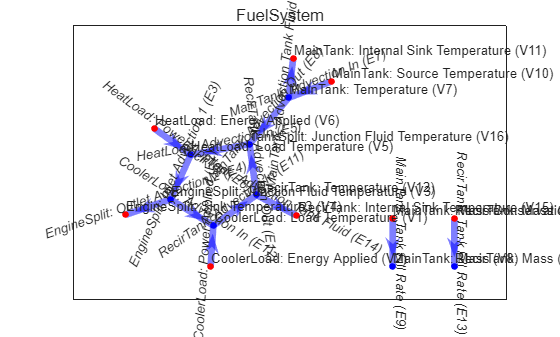

%% Dual Tank Doman Model 
clear all; close all; clc

tic
% Define Each Componnet
HeatLoad = gmt_HeatLoad("HeatLoad");
CoolerLoad = gmt_HeatLoad("CoolerLoad");
MainTank = gmt_Tank("MainTank");
RecirTank = gmt_Tank("RecirTank");
EngineSplit = gmt_SplitJunction("EngineSplit",1,2);
TankSplit = gmt_SplitJunction("TankSplit",2,1);

% Combine Each Component 
PrimaryObj = ...
    {MainTank; 
     RecirTank; 
     RecirTank; 
     CoolerLoad; 
     EngineSplit; 
     HeatLoad};

SecondaryObj = ...
    {TankSplit; 
     TankSplit; 
     CoolerLoad; 
     EngineSplit; 
     HeatLoad; 
     TankSplit};

ObjectArray = {PrimaryObj,SecondaryObj};

PortArray = ...
    [2, 1; 
     2, 2; 
     1, 2; 
     1, 2; 
     1, 2; 
     1, 3];

FilePath = string(pwd);
FuelSystem = gmt_Graph.gmt_Combine("FuelSystem",ObjectArray,PortArray);

% Match Inputs 
InputMatching = ...
[ "u2", "u5"; ...
  "u5", "(u7+u9)"; ...
  "u1", "u8"; ...
  "u4", "(u5-u8)"];

% Update Model W/ Matched Inputs
FuelSystem = FuelSystem.gmt_InputCommon(InputMatching,"BuildSim",FilePath);

% Plot Graph
FuelSystem.gmt_PlotGraph


% Generate Graph Report
FuelSystem.gmt_ReportFull


Graph Report

                   Vertex Name                   Vertex Type    Vertex State Variable    State Variable Units    Capacitance Inputs     Capacitance       Capacitance Equation                          Power Equation                      
    _________________________________________    ___________    _____________________    ____________________    __________________    ______________    ______________________    _________________________________________________________

    "CoolerLoad: Load Temperature"               "Internal"             "x1"                     "K"                     ""            "cp_f*V_1*Rho"    "Rho*V_1*cp_f*x1_dot"     "x2 - cp_f*u8*x1 + cp_f*u8*x3"            

toc

Elapsed time is 3.341356 seconds.


FuelSystem.SystemEquations.Expression

$$ans = \begin{array}{l} \left(\begin{array}{c} x_{\dot{1}}=\frac{x_{2}-{\mathrm{cp}}_{f}\,u_{8}\,x_{1}+{\mathrm{cp}}_{f}\,u_{8}\,x_{3}}{Ρ\,V_{1}\,{\mathrm{cp}}_{f}}\\ x_{\dot{3}}=-\frac{{\mathrm{cp}}_{f}\,x_{3}\,\left(u_{7}-u_{8}+u_{9}\right)-\sigma_{2}+{\mathrm{cp}}_{f}\,u_{8}\,x_{3}}{Ρ\,V_{2}\,{\mathrm{cp}}_{f}}\\ x_{\dot{5}}=\frac{x_{6}-\sigma_{2}+\sigma_{1}}{Ρ\,V_{3}\,{\mathrm{cp}}_{f}}\\ x_{\dot{7}}=-\frac{{\mathrm{cp}}_{f}\,u_{7}\,x_{7}-{\mathrm{cp}}_{f}\,u_{6}\,x_{10}+{\mathrm{cp}}_{f}\,x_{7}\,\left(u_{6}-u_{7}\right)}{{\mathrm{cp}}_{f}\,x_{8}}\\ x_{\dot{8}}=u_{6}-u_{7}\\ x_{\dot{12}}=-\frac{{\mathrm{cp}}_{f}\,u_{9}\,x_{12}-{\mathrm{cp}}_{f}\,u_{8}\,x_{1}+{\mathrm{cp}}_{f}\,x_{12}\,\left(u_{8}-u_{9}\right)}{{\mathrm{cp}}_{f}\,x_{13}}\\ x_{\dot{13}}=u_{8}-u_{9}\\ x_{\dot{16}}=\frac{{\mathrm{cp}}_{f}\,u_{7}\,x_{7}-\sigma_{1}+{\mathrm{cp}}_{f}\,u_{9}\,x_{12}}{Ρ\,V_{6}\,{\mathrm{cp}}_{f}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{cp}}_{f}\,x_{16}\,\left(u_{7}+u_{9}\right)\\ \sigma_{2}={\mathrm{cp}}_{f}\,x_{5}\,\left(u_{7}+u_{9}\right) \end{array}$$